%% 3.1 Analytische Modellierung eines Gleichstrommotors
% Regelungstechnik Labor - Vorbereitungsaufgabe
% Motor: Faulhaber 3257G012CR (unbelastet: J_Last = 0, b_Last = 0)

%% 3.1.1 Motorparameter aus Datenblatt (Faulhaber 3257G012CR)
U_N   = 12;         % Nennspannung [V]
R     = 0.41;        % Anschlusswiderstand [Ohm]
L     = 70e-6;       % Anschlussinduktivität [H] (70 µH)
k_M   = 19.1e-3;     % Drehmomentkonstante [Nm/A]
k_E   = 2e-3 * 60/(2*pi); % Generator-Spannungskonstante [V·s/rad]
                     % Datenblatt: 2 mV/min^-1 -> Umrechnung in V·s/rad
J     = 42e-7;       % Rotorträgheitsmoment [kg·m²] (42 gcm²)
b     = 0;           % Reibkoeffizient [Nm·s/rad] (unbelastet -> 0)
n_0   = 5700;        % Leerlaufdrehzahl [min^-1]

fprintf('=== Motorparameter (Faulhaber 3257G012CR) ===\n');

=== Motorparameter (Faulhaber 3257G012CR) ===


fprintf('U_N  = %.1f V\n', U_N);

U_N  = 12.0 V


fprintf('R    = %.2f Ohm\n', R);

R    = 0.41 Ohm


fprintf('L    = %.0f µH\n', L*1e6);

L    = 70 µH


fprintf('k_M  = %.1f mNm/A\n', k_M*1e3);

k_M  = 19.1 mNm/A


fprintf('k_E  = %.4f V·s/rad\n', k_E);

k_E  = 0.0191 V·s/rad


fprintf('J    = %.0f gcm² = %.2e kg·m²\n', J*1e7, J);

J    = 42 gcm² = 4.20e-06 kg·m²


fprintf('b    = %.1f (unbelastet)\n', b);

b    = 0.0 (unbelastet)



%% 3.1.2 Grundgleichungen
% 
% Elektrische Gleichung (Maschenregel):
%   U_in = R * i + L * di/dt + k_E * omega
%
% Mechanische Gleichung (Drehimpulssatz):
%   J * domega/dt = k_M * i - b * omega
%
% Zusammenhang Position/Geschwindigkeit:
%   omega = dtheta/dt
%
% Laplace-Transformation (Anfangsbedingungen = 0):
%   U(s) = (R + L*s) * I(s) + k_E * s * Theta(s)
%   J*s^2 * Theta(s) = k_M * I(s) - b*s * Theta(s)

%% 3.1.3 Übertragungsfunktion G_p1(s): Spannung -> Winkelposition
%
% Herleitung:
%   I(s) aus mechanischer Gl. isolieren:
%     I(s) = (J*s^2 + b*s) * Theta(s) / k_M
%
%   Einsetzen in elektrische Gl.:
%     U(s) = (R + L*s) * (J*s^2 + b*s) * Theta(s) / k_M  +  k_E * s * Theta(s)
%
%   Theta(s) ausklammern und umstellen:
%     G_p1(s) = Theta(s)/U(s) = k_M / [s * (L*J*s^2 + (R*J+L*b)*s + (R*b+k_E*k_M))]
%
% -> System 3. Ordnung (Integrator + PT2)

num_Gp1 = k_M;
den_Gp1 = [L*J, (R*J + L*b), (R*b + k_E*k_M), 0];
%          s^3      s^2              s^1         s^0

fprintf('\n=== G_p1(s): Spannung -> Winkelposition ===\n');


=== G_p1(s): Spannung -> Winkelposition ===


fprintf('Zähler:  %.4e\n', num_Gp1);

Zähler:  1.9100e-02


fprintf('Nenner:  [%.4e  %.4e  %.4e  %.4e]\n', den_Gp1);

Nenner:  [2.9400e-10  1.7220e-06  3.6478e-04  0.0000e+00]


fprintf('G_p1(s) = %.4e / (%.4e·s³ + %.4e·s² + %.4e·s)\n', ...
    num_Gp1, den_Gp1(1), den_Gp1(2), den_Gp1(3));

G_p1(s) = 1.9100e-02 / (2.9400e-10·s³ + 1.7220e-06·s² + 3.6478e-04·s)



%% 3.1.4 Übertragungsfunktion G_p2(s): Spannung -> Winkelgeschwindigkeit
%
% Da Omega(s) = s * Theta(s):
%   G_p2(s) = Omega(s)/U(s) = s * G_p1(s)
%   G_p2(s) = k_M / [L*J*s^2 + (R*J+L*b)*s + (R*b+k_E*k_M)]
%
% -> PT2-System (2. Ordnung)

num_Gp2 = k_M;
den_Gp2 = [L*J, (R*J + L*b), (R*b + k_E*k_M)];
%          s^2      s^1              s^0

fprintf('\n=== G_p2(s): Spannung -> Winkelgeschwindigkeit ===\n');


=== G_p2(s): Spannung -> Winkelgeschwindigkeit ===


fprintf('Zähler:  %.4e\n', num_Gp2);

Zähler:  1.9100e-02


fprintf('Nenner:  [%.4e  %.4e  %.4e]\n', den_Gp2);

Nenner:  [2.9400e-10  1.7220e-06  3.6478e-04]


fprintf('G_p2(s) = %.4e / (%.4e·s² + %.4e·s + %.4e)\n', ...
    num_Gp2, den_Gp2(1), den_Gp2(2), den_Gp2(3));

G_p2(s) = 1.9100e-02 / (2.9400e-10·s² + 1.7220e-06·s + 3.6478e-04)



%% 3.1.5 Kennwerte des PT2-Systems
% Aus den Nennerkoeffizienten von G_p2:
%   a2*s^2 + a1*s + a0
a2 = L*J;
a1 = R*J + L*b;
a0 = R*b + k_E*k_M;

% Statische Verstärkung
K_stat = k_M / a0;

% Eigenfrequenz und Dämpfung
omega_n = sqrt(a0 / a2);
zeta    = a1 / (2 * sqrt(a0 * a2));

fprintf('\n=== Kennwerte des PT2 ===\n');


=== Kennwerte des PT2 ===


fprintf('Statische Verstärkung K = %.4f\n', K_stat);

Statische Verstärkung K = 52.3599


fprintf('Eigenfrequenz omega_n   = %.2f rad/s\n', omega_n);

Eigenfrequenz omega_n   = 1113.89 rad/s


fprintf('Dämpfungsgrad zeta      = %.4f\n', zeta);

Dämpfungsgrad zeta      = 2.6291


if zeta > 1
    fprintf('-> System ist überdämpft (zeta > 1)\n');
elseif zeta == 1
    fprintf('-> System ist kritisch gedämpft (zeta = 1)\n');
else
    fprintf('-> System ist unterdämpft (zeta < 1)\n');
end

-> System ist überdämpft (zeta > 1)



% Zeitkonstanten (nur bei überdämpftem System sinnvoll)
if zeta >= 1
    % Pole berechnen
    p1 = (-a1 + sqrt(a1^2 - 4*a2*a0)) / (2*a2);
    p2 = (-a1 - sqrt(a1^2 - 4*a2*a0)) / (2*a2);
    tau1_ana = -1/p1;
    tau2_ana = -1/p2;
    fprintf('Pol 1 = %.2f -> tau1 = %.6f s\n', p1, tau1_ana);
    fprintf('Pol 2 = %.2f -> tau2 = %.6f s\n', p2, tau2_ana);
end

Pol 1 = -220.11 -> tau1 = 0.004543 s


Pol 2 = -5637.03 -> tau2 = 0.000177 s



%% 3.1.6 Zustandsraummodell
%
% Zustandsgrößen:  x1 = theta (Winkelposition)
%                  x2 = omega (Winkelgeschwindigkeit)
%                  x3 = i     (Strom)
% Eingang:         u  = U_in
% Ausgang:         y  = theta
%
% Differentialgleichungen:
%   dx1/dt = x2
%   dx2/dt = -(b/J)*x2 + (k_M/J)*x3
%   dx3/dt = -(k_E/L)*x2 - (R/L)*x3 + (1/L)*u
%
% Matrixform: dx/dt = A*x + B*u,  y = C*x + D*u

A = [0,     1,       0     ;
     0,    -b/J,     k_M/J ;
     0,    -k_E/L,  -R/L  ];

B = [0   ;
     0   ;
     1/L];

C = [1, 0, 0];

D = 0;

fprintf('\n=== Zustandsraummodell ===\n');


=== Zustandsraummodell ===


fprintf('Zustandsgrößen: x1 = theta, x2 = omega, x3 = i\n');

Zustandsgrößen: x1 = theta, x2 = omega, x3 = i


fprintf('Eingang: u = U_in,  Ausgang: y = theta\n\n');

Eingang: u = U_in,  Ausgang: y = theta




fprintf('A = \n');

A = 


disp(A);

   1.0e+03 *

         0    0.0010         0
         0         0    4.5476
         0   -0.2728   -5.8571



fprintf('B = \n');

B = 


disp(B);

   1.0e+04 *

         0
         0
    1.4286



fprintf('C = \n');

C = 


disp(C);

     1     0     0



fprintf('D = \n');

D = 


disp(D);

     0



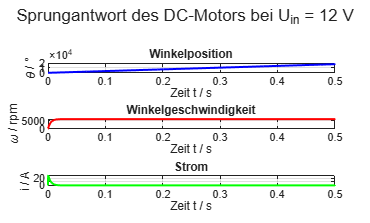


%% 3.1.7 Simulation der Sprungantwort (ohne Control System Toolbox)
% Numerische Integration mit ode45

tspan = [0 0.5];  % Simulationszeit [s]
x0 = [0; 0; 0];   % Anfangsbedingungen

% Sprung von U_N = 12 V
[t_sim, x_sim] = ode45(@(t,x) A*x + B*U_N, tspan, x0);

figure('Name','Sprungantwort - Analytisches Modell');

subplot(3,1,1);
plot(t_sim, x_sim(:,1) * 180/pi, 'b-', 'LineWidth', 1.5);
xlabel('Zeit t / s');
ylabel('\theta / °');
title('Winkelposition');
grid on;

subplot(3,1,2);
plot(t_sim, x_sim(:,2) * 60/(2*pi), 'r-', 'LineWidth', 1.5);
xlabel('Zeit t / s');
ylabel('\omega / rpm');
title('Winkelgeschwindigkeit');
grid on;

subplot(3,1,3);
plot(t_sim, x_sim(:,3), 'g-', 'LineWidth', 1.5);
xlabel('Zeit t / s');
ylabel('i / A');
title('Strom');
grid on;

sgtitle('Sprungantwort des DC-Motors bei U_{in} = 12 V');